clear all

data=importdata("Large_Triangle008_C1_vector_table_50grid_50window_gaussian.csv");

X=data.data(:,1);

Y=data.data(:,2);

dx=data.data(:,4);

dy=data.data(:,5);

Ori=data.data(:,6); %Orientation (in degrees angle)

En=data.data(:,8); %Energy 



theta1=reshape(Ori,202,130); %x=235,y=136 for 003, x=241,y=142 for 004,  x=248, y=146 for 006.
%for 45A45A90A we have: x=146, y=142 for 003. x=150, y=152 for 006. x=147, y=142 for 008.
%for 60A60A60A we have: x=141, y=132 for 005. x=135, y=117 for 006. x=142, y=126 for 015.
%for 120A30A30A we have: x=202, y=135 for 002. x=203, y=134 for 003. x=202,
%y=130 for 008.
theta1=transpose(theta1);

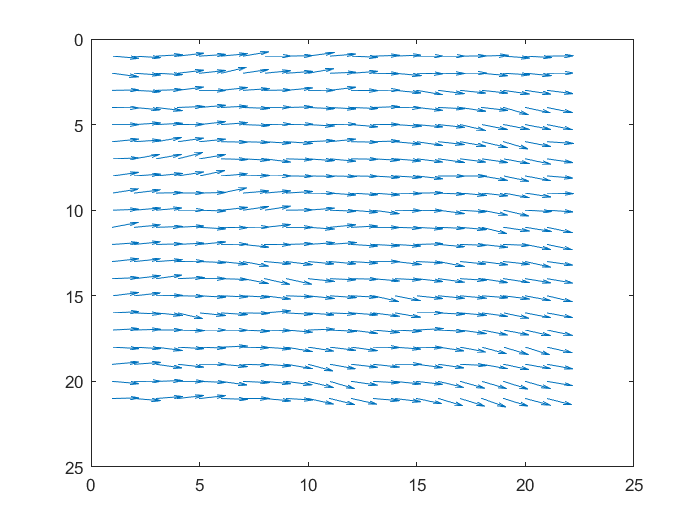

%theta2=theta1(59:79, 73:93)/180*pi;                  %theta1(row,column)
%theta2=degree_state/180*pi;
theta2=S;

%theta2=theta2(1:21,2:22);

figure(1); quiver(cos(theta2),sin(theta2))
set (gca,'Ydir','reverse')


phi=transpose(theta2);
phi=reshape(phi,1,[]);
phi=transpose(phi);


H=size(theta2,1);
L=size(theta2,2);

N=H*H;

E=zeros(H,L);

%load('Simulation_data.mat');
%SimData;

phi_1=(phi-mean(phi));

phi_N = phi_1(N);

b = phi_1(phi_1 ~= phi_N);




[M, M9] = Matrixcalculation(H);

M_ij=M(1:N-1, 1:N-1);

M9_ij=M9(1:N-1, 1:N-1);



for i = 1 : H*H-1
M_Nj(1,i)=M(N, i);
M_iN(i,1)=M(i, N);
M9_Nj(1,i)=M9(N, i);
M9_iN(i,1)=M9(i, N);
end
M_NN=M(N,N);
M9_NN=M9(N,N);

Mny=M_ij-M_Nj-M_iN+M_NN;
M9ny=M9_ij-M9_Nj-M9_iN+M9_NN;


%K3 kan aldrig være mindre end K1, ellers skal jeg bare tage den absolutte
%værdi og dermed kender jeg kun forskellen mellem K3 og K1
cd('cube-main')
cd('path_to_cube')
obs=b;
N=H*H;
model=struct('genu',@(obs) rand(1,2));
model.u2theta=@(u,obs) [-400*log(u(1)), -400*log(u(2))]; %theta(1)=K1 and theta(2)=K3-K1
model.logl=@(phi,theta) logl(theta(1), theta(2), obs, N, Mny, M9ny);
model.labels={'K1', 'K3'};
results1=cube_main(obs,model);

After 500 processed samples: Zrat = 8.7e+26
After 1000 processed samples: Zrat = 77
After 1500 processed samples: Zrat = 0.436
After 2000 processed samples: Zrat = 0.0298
After 2500 processed samples: Zrat = 0.00243
Generated 2878 samples for Model 1.
CUBE is done.
Elapsed time is 303.864962 seconds.


function b1 = logl(K1, K3, obs, N, Matrix, M9)

    Mat = Matrix + (K3/K1-1) * M9; %her har vi divideret K1 på alle led
    
    M = chol(Mat, "lower");

    y = M' * obs;

    b1 = sum(log(diag(M))) - N * 0.5 * log(2 * pi / K1) - K1 / 2 * (y' * y);

end






function [Matrix, M9] = Matrixcalculation(H)
M9=zeros(H*H,H*H);
Matrix=zeros(H*H,H*H);
for i = 1:H*H
    if mod(i,H) ~= 0        % Ikke sidste i rækken
        Matrix(i,i+1) = - 1;
        Matrix(i+1,i) = - 1;
    end
    
end
for i =1:H*H-H
        Matrix(i+H,i) = - 1;
        Matrix(i,i+H) = - 1;
end
for i = 1:H*H
    rowSum = sum(abs(Matrix(i,:)));
    Matrix(i,i) = rowSum*1;  % epsilon fx 1e-6
end

% Definer offset-naboer (venstre/højre i 2D gitter)
for i = 1:H*H
    if mod(i,H) ~= 0        % Ikke sidste i rækken
        M9(i,i+1) = - 1;
        M9(i+1,i) = - 1;
    end
end
for i = 1:H*H
    rowSum = sum(abs(M9(i,:)));
    M9(i,i) = rowSum*1;  % epsilon fx 1e-6
end
%Matrix(1+H,1+H)=Matrix(1+H,1+H)+1E-6;
end






